## EEL839 - Transmissão Digital

Trabalho sobre o artigo: Adversarial training based channel estimation to mitigate jamming attacks in OFDM systems

Guilherme Araujo Thomaz

Este código implementa a parte do trabalho referente às simulações no Matlab para geração dos dados utilizados para treinar a rede neural.

### Parâmetros para plotagem

linewidth  = 2;
fontname   = 'Times New Roman';
fontsize   = 20;
markersize = 10;

### Parâmetros para simulação

N = 1024;           % Número de subportadoras (símbolos por bloco)
ts = 200e-9;        % Tempo de um símbolo
fs = 1/ts;          % Taxa de amostragem
fc = 2e9;           % Frequência da portadora
v = 4/3.6;          % Velocidade em m/s
L = 10;             % Ordem do canal
B = 4;              % Bits por símbolo
Q = 2^B;            % Tamanho da constelação
N_blocks = 1;       % Número de blocos transmitidos
N_FFT = 1024;
SNR = 30;           % Decibeis, essa é a SNR da estimativa do canal
K = 5;              % Redundância
S = N+K;            % Tamanho total do bloco (amostras + redundância)

### Geração do canal

% Créditos para a pesquisa de Miranda, L. D. S. G. (2021). 
% ESTIMADOR DE CANAIS EM SISTEMA OFDM UTILIZANDO APRENDIZADO DE MAQUINA 
% (Doctoral dissertation, Universidade Federal do Rio de Janeiro).
% O trabalho me ajudou a implementar esta parte.
c = physconst('LightSpeed'); % Velocidade da luz no espaço livre
max_doppler_shift = v*fc/c;

% Teste com canal diferente, mais fácil de lidar
%max_doppler_shift = 1;
chan = stdchan('cdmaTUx',fs,max_doppler_shift); % Gera canal

### Testando canal pela resposta ao impulso

%chan.Visualization = 'Frequency response';
%chan.Visualization = 'Impulse and frequency responses';
%channel.SamplesToDisplay = '100%';
%y = chan(0);

data = zeros(100,1); % Esse 100 poderia ser qualquer coisa
data(1) = 1; % Gera impulso
h_coef = chan(data);
h_coef = h_coef(7:L+6);

### Fixando canal de teste

h_coef = [
    0.6116 + 0.0538i;
   -0.3152 - 0.0319i;
   -0.3045 + 0.1517i;
   -0.4365 + 0.2198i;
   -0.1024 - 0.3100i;
   -0.1597 - 0.1125i;
    0.0210 + 0.2288i;
    0.1516 - 0.0144i;
   -0.1085 - 0.1425i;
   -0.0022 + 0.0865i;
];

### Plotando a resposta ao impulso do canal (no tempo)

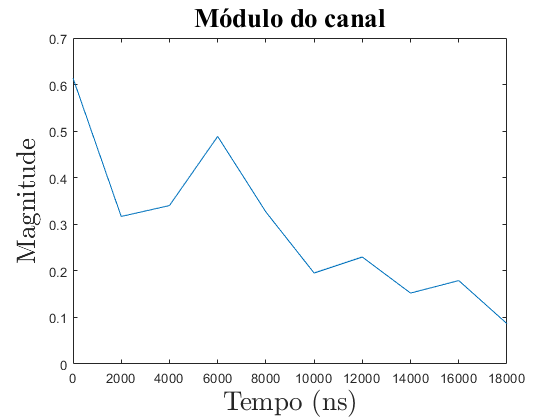

t = (0:ts:((L-1)*ts))*10e9;
%plot(t,real(h_coef));
%title('Parte real do canal','fontname',fontname,'fontsize',fontsize);
%xlabel('Tempo (ns)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
%ylabel('Magnitude','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
%plot(t,imag(h_coef));
%title('Parte imaginária do canal','fontname',fontname,'fontsize',fontsize);
%xlabel('Tempo (ns)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
%ylabel('Magnitude','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
plot(t,abs(h_coef));
title('Módulo do canal','fontname',fontname,'fontsize',fontsize);
xlabel('Tempo (ns)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('Magnitude','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

### Resposta em frequência do canal

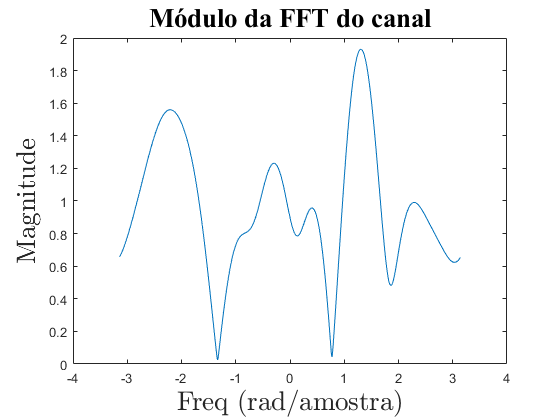

h_fft = fft(h_coef,N_FFT);
freq = 2*pi*linspace(-0.5,0.5,N_FFT);
plot(freq, abs(h_fft));
title('Módulo da FFT do canal','fontname',fontname,'fontsize',fontsize);
xlabel('Freq (rad/amostra)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('Magnitude','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

### Preparação para transmissão e recepção OFDM

A_cp = [zeros(K,N-K) eye(K); eye(N)];       % Matriz de adição de redundância
R_cp = [zeros(M,K) eye(M)];                 % Matriz de remoção de redundância
pilot_symbols = rand(1,N)+1i*rand(1,N);     % Símbolos combinados para estimação de canal
x  = zeros(N*N_blocks,1);                   % Inicializa bloco 

### Geração do OFDM